# Ejercicio 2

Se tiene un cuadrado de lado "p" con una parábola que va de 0 a "p", de acuerdo con la figura, tenemos la siguiente igualdad:


$$-x^2 +p\;x=-x\left(x-p\right)$$


Para que el área de la parábola sea la misma que la de la baldosa, se toma que el área total entre 2, es el área de la parábola y para que la parábola se pueda desplazar hacia abajo, su ecuación debe dividirse entre un valor "q", por lo que se tiene la siguiente integral:


$$\int_0^p \frac{-x^2 +p\;x}{q}\;\mathrm{dx}\;=\frac{p^2 }{2}$$


Para encontrar "q", resolvemos la integral sin dividir la ecuación entre "q" y tenemos esto:


$$\int_0^p -x^2 +p\;x\;\mathrm{dx}=\frac{p^3 }{6}$$


Luego, multiplicamos eso por $\frac{1}{q}$ y tenemos que:


$$\frac{p^3 }{6}\cdot \frac{\;1}{q}=\frac{p^2 }{2}$$


Por lo tanto resolvemos para q y tenemos:


$$q=\frac{p}{3}$$


Por último, con esto sabemos que la ecuación de la parábola es:


$$\frac{-3x^2 +3p\;x}{p}$$


y con una integral definida de 0 a "p" para obtener su área.

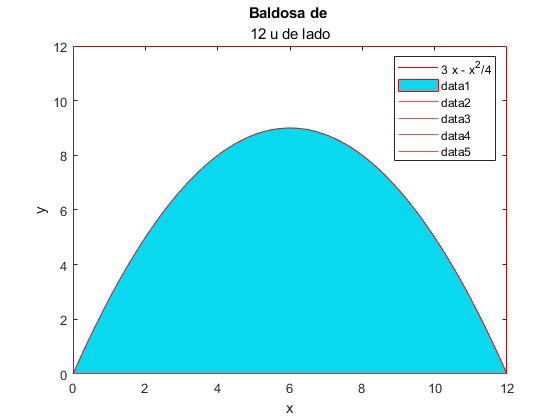

clc; clear
close all

R = rand();
G = rand();
B = rand();

syms x

p = 12;
eq = (-3 * x^2 + 3 * p * x) / p;
fplot(eq, [0 p], "Color", "r")

legend("-DynamicLegend")
legend("show")
hold on

r = linspace(0, p, 100);
s = (-3 * r.^2 + 3 * p * r) / p;
area(r, s, "FaceColor", [R G B], "EdgeColor", "r")

yline([0 p], "Color", "r")
xline([0 p], "Color", "r")

n = num2str(p) + " u de lado";
title("Baldosa de ", n)
xlabel('x')
ylabel('y')


areaTotalBaldosa = p * p

areaTotalBaldosa = 144

areaParabola = int(abs(eq), 0, p)

$$areaParabola = 72$$

areaBaldosaMenosParabola = areaTotalBaldosa - areaParabola

$$areaBaldosaMenosParabola = 72$$